load ('Samsung_30Q_18650_pack.mat');
load ('VoltaicSystems_P110.mat');

addpath("Functions/");
addpath("Simulink/");
addpath("Bode/");

% Switching frequency:
boost.f = 1 * 10^5; % [Hz]
boost.T = 1/boost.f;

% Measurement filter cut-off:
boost.mfc = 2000; %[Hz]
boost.Tmfc = 1/(2*pi*boost.mfc);

% Maximum duty cycle that can be achieved:
boost.D_max = 1 - pv_data.Umpp/Bat.Ubat_nom; % MPP mode of operation

% Passive elements:
boost.Rt = 1*10^5;
boost.RL = 10 * 10^-3;
boost.Ru = 1;
boost.L = 50 * 10^-6;
boost.Cu = 1500 * 10^-6;
boost.Ci = 1200 * 10^-6;
boost.Cbat = Bat.Qbat_tot/(Bat.Ubat_charged - Bat.Ubat_cut_off);

## PV resistance:

pv_in.G = 1000;     %[W/m^2]
pv_in.t = 25;       %[deg]
pv_in.ramp = 1;     %[/]

pv = calc_pv_res("Solar_v2", pv_in);

clear pv_in;

## Pick operating point:

% Pick operating point for simulation:
boost.Upv_op = 0.98 * pv.Uoc;
% boost.Upv_op = pv.Umpp + 0.001;

% Upv -> Ipv:
idx = find(pv.Upv >= boost.Upv_op, 1);
boost.Ipv_op = pv.Ipv(idx);

clear idx;

## Step input Settings:

% Step input settings:
stepp.step_time = 20 * 10^-3; % [ms]
stepp.sim_time = 50 * 10^-3; % [ms]
% stepp.step_time = 30 * 10^-3; % [ms]
% stepp.sim_time = 100 * 10^-3; % [ms]

% Ir, Refrence current:
stepp.ir01 = boost.Ipv_op;
stepp.ir02 = boost.Ipv_op + 0.1;

% Upv, Input voltage:
% stepp.upv1 = interp1(pv.Ipv, pv.Upv, stepp.ir01, 'linear', 'extrap');
% stepp.upv2 = interp1(pv.Ipv, pv.Upv, stepp.ir02, 'linear', 'extrap');

[~, idx1] = min(abs(pv.Ipv - stepp.ir01));
[~, idx2] = min(abs(pv.Ipv - stepp.ir02));

stepp.upv1 = pv.Upv(idx1);
stepp.upv2 = pv.Upv(idx2);

% CCM:
stepp.d1 = ccm_m_param(boost, Bat, pv, stepp.ir01).D0;
stepp.d2 = ccm_m_param(boost, Bat, pv, stepp.ir02).D0;

clear idx1 idx2;

## Steady state operating point parameters:

% CCM mode with compensation ramp parameters:
ccm_m_op = ccm_m_param(boost, Bat, pv, boost.Ipv_op);
display('CCM parameters:')

CCM parameters:


Upv0 = ccm_m_op.Upv0

Upv0 = 6.9580

Ipv0 = ccm_m_op.Ipv0

Ipv0 = 0.2983

Ubat0 = ccm_m_op.Ubat0

Ubat0 = 10.8000

Im0 = ccm_m_op.Im0

Im0 = -0.2560

m0 = ccm_m_op.m0

m0 = 1.6660e+04

ro = ccm_m_op.ro

ro = 0.6792

L_lim = ccm_m_op.L_lim

L_lim = 9.3416e-05

G_incr_pv = ccm_m_op.G_incr_pv

G_incr_pv = -2.2758

D0 = ccm_m_op.D0

D0 = 0.3557

Ir_lim = ccm_m_op.Ir_lim

Ir_lim = 0.5543

% DCM mode parameters:
dcm_op = dcm_param(boost, Bat, pv, boost.Ipv_op);
display('DCM parameters:')

DCM parameters:


Upv0 = dcm_op.Upv0

Upv0 = 6.9580

Ipv0 = dcm_op.Ipv0

Ipv0 = 0.2983

Ir0 = dcm_op.Ir0

Ir0 = 0.2983

Ubat0 = dcm_op.Ubat0

Ubat0 = 10.8000

m0 = dcm_op.m0

m0 = 1.6660e+04

ro = dcm_op.ro

ro = 0.4807

G_incr_pv = ccm_m_op.G_incr_pv

G_incr_pv = -2.2758

D0 = ccm_m_op.D0

D0 = 0.3557


sim_op = dcm_op;

clear Upv0 Ipv0 Ir0 Ubat0 Im0 m0 ro L_lim D0 G_incr_pv

## Colors:

% 0, 0, 0;                    % black
% 0, 0, 1;                    % blue
% 1, 0, 0;                    % red
% 0, 1, 0;                    % green
% 0.9290, 0.6940, 0.1250;     % yellow-gold
% 0.8500, 0.3250, 0.0980;     % reddish-orange

myColors = [
    0, 0, 0;                    % black
    0, 0, 1;                    % blue
    1, 0, 0;                    % red
    0, 1, 0;                    % green
];

## CCM,CV (compensation ramp):

[ccm_m_sys, ccm_m_separate_tfs] = ccm_m_calc_tfs(boost, ccm_m_op);

plot_data.t = linspace(0, 0.2*10^-3,1000);
plot_data.labels = {"Full sys", "PT1 aprox"};
plot_data.colors = myColors;
plot_data.linestyles = {'-','--'};
plot_data.y_label = "U_b_a_t [mV]";

% Refrence current:
plot_data.fgtitle = "U_b_a_t response to I_r, CCM-CV";

Ir.full = ccm_m_separate_tfs.G_Ubat_Ir;
Ir.red = ccm_m_separate_tfs.G_Ubat_Ir;

Tp1 = ccm_m_sys.Tp1

Tp1 = 0.0011

Tp2 = ccm_m_sys.Tp2

Tp2 = 7.0174e-06

% wp3 = 1/ccm_m_sys.Tp3
Tz1 = ccm_m_sys.Tz1

Tz1 = 5.0948e-06

Tz2 = ccm_m_sys.Tz2

Tz2 = 5.6139e-06

Zeta = ccm_m_sys.zeta

Zeta = 6.3975


wp1 = 1/Tp1

wp1 = 881.2559

wp2 = 1/Tp2

wp2 = 1.4250e+05

wz1 = 1/Tz1

wz1 = 1.9628e+05

wz2 = 1/Tz2

wz2 = 1.7813e+05

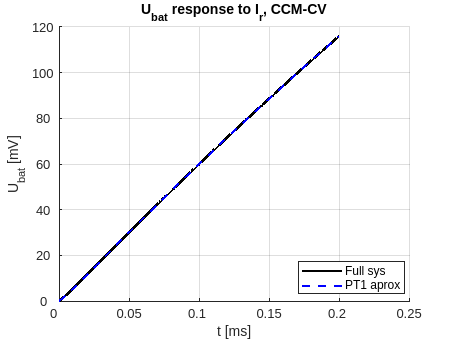


plot_step_responses(Ir, plot_data);


% Input voltage:
plot_data.fgtitle = "U_b_a_t response to U_p_v, CCM-CV";

Upv.full = ccm_m_separate_tfs.G_Ubat_Upv;
Upv.red = ccm_m_separate_tfs.G_Ubat_Upv_red

Upv = struct with fields:
    full: [1×1 tf]
     red: [1×1 tf]


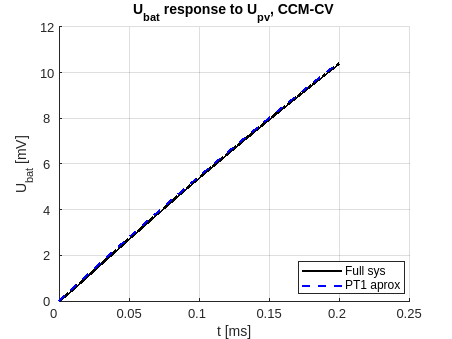


plot_step_responses(Upv, plot_data);


Gipv = ccm_m_separate_tfs.G_Ubat_Ir

Gipv =
 
       3.689e-06 s + 0.724
  ------------------------------
  7.963e-09 s^2 + 0.001142 s + 1
 
Continuous-time transfer function.
Model Properties


Gupv = ccm_m_separate_tfs.G_Ubat_Upv

Gupv =
 
      3.633e-07 s + 0.06472
  ------------------------------
  7.963e-09 s^2 + 0.001142 s + 1
 
Continuous-time transfer function.
Model Properties



clear Tp1 Tp2 Tz1 Tz2 Zeta;
clear Gupv Gipv;
clear Upv Ir;
clear plot_data;

## DCM, CV

[dcm_sys, dcm_separate_tfs] = dcm_calc_tfs(boost, dcm_op);

dcm_separate_tfs.G_Ubat_Ir_full;
dcm_separate_tfs.G_Ubat_Ir

ans =
 
      0.306
  --------------
  0.001186 s + 1
 
Continuous-time transfer function.
Model Properties



dcm_separate_tfs.G_Ubat_Upv_full;
dcm_separate_tfs.G_Ubat_Upv

ans =
 
     0.01328
  --------------
  0.001186 s + 1
 
Continuous-time transfer function.
Model Properties


## Plant model:

% CCM-CV:
[Gp_ccm, plant_ccm_param] = sys_ccm(ccm_m_sys, ccm_m_op, boost);

Gp_ccm

Gp_ccm =
 
               0.0004772 s + 0.7047
  ----------------------------------------------
  5.952e-11 s^3 + 8.907e-07 s^2 + 0.001873 s + 1
 
Continuous-time transfer function.
Model Properties



1/plant_ccm_param.Tp1

ans = 1.5172e+03

1/plant_ccm_param.Tp2

ans = 881.2559

1/plant_ccm_param.Tp3

ans = 1.2566e+04

1/plant_ccm_param.Tz

ans = 1.4767e+03


% DCM-CV:
[Gp_dcm, plant_dcm_param] = sys_dcm(dcm_sys, dcm_op, boost);

1/plant_dcm_param.Tp1

ans = 1.5172e+03

1/plant_dcm_param.Tp2

ans = 843.3615

1/plant_dcm_param.Tp3

ans = 1.2566e+04

1/plant_dcm_param.Tz

ans = 1.5033e+03


Gp_dcm

Gp_dcm =
 
               0.0002017 s + 0.3032
  ----------------------------------------------
  6.219e-11 s^3 + 9.283e-07 s^2 + 0.001924 s + 1
 
Continuous-time transfer function.
Model Properties



% figure;
% step(Gp_dcm)

clear plot_data;

## Bode plot

z = zero(Gp_dcm);
p = pole(Gp_dcm);
[~, idx_z] = sort(abs(z), 'ascend'); % Sort zeros by magnitude
[~, idx_p] = sort(abs(p), 'ascend'); % Sort poles by magnitude
z_sorted = abs(z(idx_z));
p_sorted = abs(p(idx_p));

p_sorted

p_sorted = 1.0e+04 *

    0.0472
    0.1105
    1.2566


z_sorted

z_sorted = 16.2977

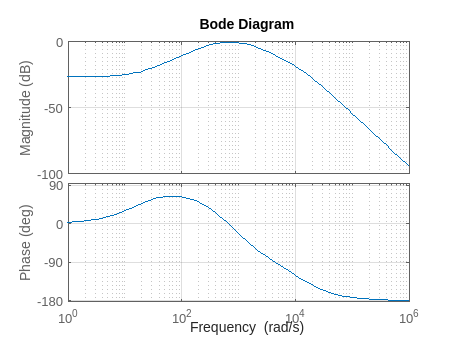

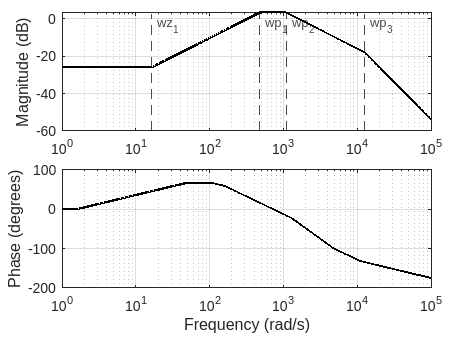


w = logspace(0, 5, 1000);

figure();
bode(Gp_dcm);
grid on;

draw_bode(Gp_dcm, w)


clear z p idx_z idx_p z_sorted p_sorted;

## Regulator (symmetrical optimum):

% Textbook:
% Kp = plant_ccm_param.K;
% Tsum = plant_ccm_param.Tp2 + plant_ccm_param.Tp3;
% Ti = 4*Tsum;
% KR = 1/Kp*Ti/(2*Tsum);
% Gr = tf([KR*Ti, KR], [Ti, 0])

% Time constants:
z = zero(Gp_ccm);
p = pole(Gp_ccm);
[~, idx_z] = sort(abs(z), 'ascend'); % Sort zeros by magnitude
[~, idx_p] = sort(abs(p), 'ascend'); % Sort poles by magnitude
z_sorted = abs(z(idx_z));
p_sorted = abs(p(idx_p));

% Open loop gain:
% dL1 = 

% Bjazic
Mpg = 20;
PM = 50;
a = PM/14;

% System poles:
wz = 1/plant_ccm_param.Tz

wz = 422.7995

wu = 1/plant_ccm_param.Tp1

wu = 471.9547

wp1 = 1/plant_ccm_param.Tp2

wp1 = 884.7103

wmf = 1/plant_ccm_param.Tp3

wmf = 1.2566e+04


wc = wmf/a

wc = 3.5186e+03

wi = wc/a

wi = 985.2035


Ti = 1/wi;
Kr = (3535.9*Ti)/(plant_ccm_param.K)

Kr = 4.6836

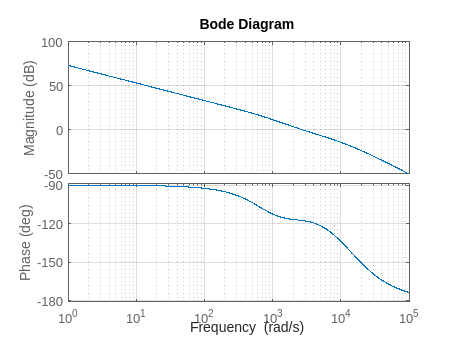

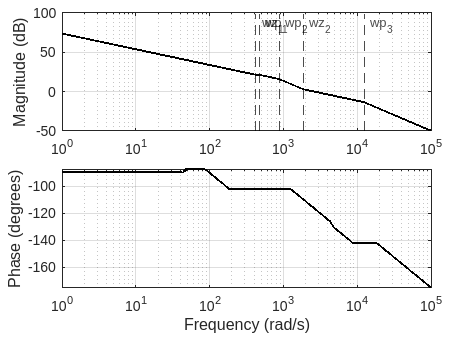


% PID tuner:
Ti = 5.39 * 10^-4;
Kr = 3.286;

% Gr = tf([Kr*Ti, Kr], [Ti, 0])
Gr = tf([Kr, Kr/Ti], [1, 0]); 

G_full = Gr * Gp_ccm;

w = logspace(0, 5, 1000);

figure();
bode(G_full, w);
grid on;

z = zero(G_full);
p = pole(G_full);
[~, idx_z] = sort(abs(z), 'ascend'); % Sort zeros by magnitude
[~, idx_p] = sort(abs(p), 'ascend'); % Sort poles by magnitude
z_sorted = abs(z(idx_z));
p_sorted = abs(p(idx_p));

draw_bode(G_full, w);

## linear vs nonlinear:

sim_op = ccm_m_op;

lin = sim("Simulink/Strujni_nacin_v2.slx");

nonlin = sim("Simulink/Nelinearni_test.slx");

% Extract
IL_nonlin = nonlin.get("IL").Data;
Ubat_nonlin = nonlin.get("Ubat").Data;
Ubat_lin = lin.get("Ubat").Data;
t = lin.get("Ubat").Time * 1000;  % convert to ms

% Time period to cut from graph (10 ms)
t_start = 10;  % [ms]
idx = t >= t_start;

% Shorten arrays
t = t(idx) - t_start;
IL_nonlin = IL_nonlin(idx);
Ubat_nonlin = Ubat_nonlin(idx);
Ubat_lin = Ubat_lin(idx);

fig = figure;

% % Set paper properties on the figure
% fig.PaperUnits = 'centimeters';
% fig.PaperSize = [21 29.7];           % width x height in inches
% fig.PaperPosition = [0 0 8 4.5];   % position on paper (fill whole paper)

% for 11 x 9 (W x H)
width_px = round(11/2.54 * 300); % ~1335 pixels
height_px = round(9/2.54 * 300); % ~1146 pixels

fig = figure('Units','pixels', 'Position', [100 100 width_px height_px]); % W x H

% Plotting a 3 x 1 array of graphs:
layout = tiledlayout(3,1);
layout.TileSpacing = 'compact';
layout.Padding = 'compact';

% Output voltage:
nexttile;
hold on;
plot(t, Ubat_nonlin, 'b', 'LineWidth', 1.5);
plot(t, Ubat_lin, '--r', 'LineWidth', 2.5);
hold off;
xlabel("\it{t}\rm [ms]");
yl = ylabel("\it{U_{bat}}\rm [V]")

yl =   Text (\it{U_{bat}}\rm [V]) with properties:

                 String: '\it{U_{bat}}\rm [V]'
               FontSize: 11
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'center'
               Position: [-1.4290 10.8700 -1.0000]
                  Units: 'data'

  Show all properties


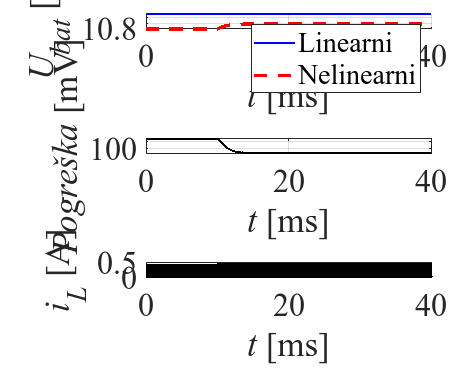

% yl.Position(1) = -1;
legend("Linearni", "Nelinearni");
axis auto;
ax = gca;
ax.FontSize = 24;
ax.FontName = 'Times New Roman';
grid on;

% Error:
nexttile;
error = (Ubat_nonlin - Ubat_lin)*1000;
plot(t, error, 'k', 'LineWidth', 1.5);
yl = ylabel("\it{Pogreška}\rm [mV]");
% yl.Position(1) = -1;
xlabel("\it{t}\rm [ms]");
ax = gca;
ax.FontSize = 24;
ax.FontName = 'Times New Roman';
grid on;

% Struja zavojnice:
nexttile;
plot(t, IL_nonlin, 'k', 'LineWidth', 1.5);
yl = ylabel("\it{i_L}\rm [A]");
% yl.Position(1) = -1;
xlabel("\it{t}\rm [ms]");
ax = gca;
ax.FontSize = 24;
ax.FontName = 'Times New Roman';
grid on;

exportgraphics(gcf, 'graf_ccm_full.png', 'Resolution', 300);

## Plot PV characteristic:

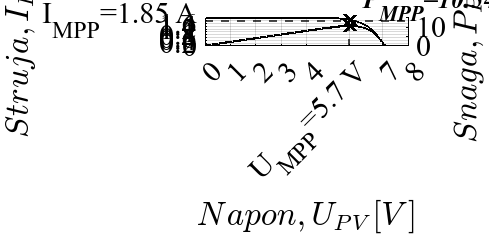

% for 11 x 9 (W x H)
width_px = round(15.52/2.54 * 300); % ~1335 pixels
height_px = round(7.5/2.54 * 300); % ~1146 pixels

fig = figure('Units','pixels','Position',[100 100 width_px height_px]);

% Set default font for axes and text within this figure
set(fig, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 24);
set(fig, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 24);

hold on;
grid on;

% --- Left axis: I-V curve ---
yyaxis left
plot(pv.Upv, pv.Ipv, '-k', 'LineWidth', 2);
ylabel("${Struja, I_{PV} [A]}$", 'Interpreter', 'latex');

% Incremental conductance:
% Ir = 0;
% U1 = interp1(pv.Ipv, pv.Upv, Ipv0, 'linear', 'extrap');
% idx = find(pv.Upv >= U1, 1);
% Gpv = (pv.Ipv(idx+1) - pv.Ipv(idx-1)) / (pv.Upv(idx+1) - pv.Upv(idx-1))
% x = linspace(pv.Upv(idx) - 0.5, pv.Upv(idx) + 0.5, 200);
% y = pv.Ipv(idx) + Gpv * (x - pv.Upv(idx));
% hold on;
% plot(x, y, '-r', 'LineWidth', 1.3);

% --- Right axis: P-V curve (still black) ---
yyaxis right
plot(pv.Upv, pv.Ppv, '-k', 'LineWidth', 2);
ylabel("${Snaga, P_{PV} [W]}$", 'Interpreter', 'latex');

% --- Set both axes black ---
ax = gca;
ax.YColor = 'k';
ax.XColor = 'k';

% --- Common x-axis ---
xlabel("${Napon, U_{PV} [V]}$", 'Interpreter', 'latex');

% --- Add MPP markers ---
yyaxis left
plot(pv.Umpp, pv.Impp, 'xk', 'MarkerSize', 10, 'LineWidth', 3);  % I-V curve
yyaxis right
plot(pv.Umpp, pv.Pmpp, 'xk', 'MarkerSize', 10, 'LineWidth', 3);  % P-V curve

% --- Add Pmpp text label ---
text(pv.Umpp, pv.Pmpp, ...
    sprintf('  P_{MPP}=%.2f W', pv.Pmpp), ...
    'VerticalAlignment','bottom','HorizontalAlignment','left', ...
    'FontSize',20,'FontName','Times New Roman', ...
    'FontWeight','bold','FontAngle','italic', ...
    'Interpreter','tex');
% --- MPP guide lines ---
yyaxis left
xline(pv.Umpp, '--k', 'LineWidth', 1.5);   % vertical line at Umpp
yline(pv.Impp, '--k', 'LineWidth', 1.5);   % horizontal line at Impp

% --- Add x/y ticks only for MPP and remove overlap ---
xt = xticks;
yt = yticks;

% Remove ticks too close to Umpp / Impp (optional)
xt(abs(xt - pv.Umpp) < 0.2 * pv.Umpp) = [];
yt(abs(yt - pv.Impp) < 0.1 * pv.Impp) = [];

% Add the MPP tick positions back
xt = sort([xt, pv.Umpp]);
yt = sort([yt, pv.Impp]);

% Build new labels
xtlbl = string(xt);
ytlbl = string(yt);

% Label Umpp and Impp
[~, ix] = min(abs(xt - pv.Umpp));
xtlbl(ix) = sprintf('U_{MPP}=%.1f V', pv.Umpp);

[~, iy] = min(abs(yt - pv.Impp));
ytlbl(iy) = sprintf('I_{MPP}=%.2f A', pv.Impp);

% Apply new ticks and labels
xticks(xt);
yticks(yt);
xticklabels(xtlbl);
yticklabels(ytlbl);

% --- Final formatting ---
set(gca, 'TickLabelInterpreter', 'tex');
set(findall(gcf,'type','text'), 'Color', 'k');

% --- Set both axes black ---
ax = gca;
ax.YColor = 'k';
ax.XColor = 'k';

grid on;

exportgraphics(gcf, 'graf_pv_characteristic.png', 'Resolution', 300);

## Pole and zero plot:

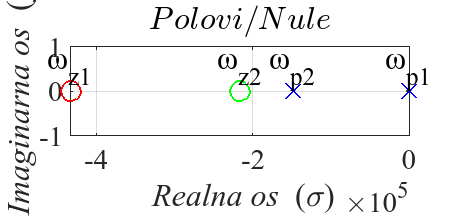

% for 11 x 9 (W x H)
width_px = round(15.52/2.54 * 300); % ~1335 pixels
height_px = round(7.5/2.54 * 300); % ~1146 pixels

z1 = zero(ccm_m_separate_tfs.G_Ubat_Ir);
z2 = zero(ccm_m_separate_tfs.G_Ubat_Upv);
p = pole(ccm_m_separate_tfs.G_Ubat_Upv);
p2 = p(1);
p1 = p(2);
clear p;

fig = figure('Units','pixels','Position',[100 100 width_px height_px]);

%% --- Compute text offset based on axis scale ---
ax = gca;
xrange = diff(ax.XLim);
yrange = diff(ax.YLim);

% dx = 0.05 * xrange;   % larger offset than before
% dy = 0.03 * yrange;

% Set default font for axes and text within this figure
set(fig, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 24);
set(fig, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 24);

hz1 = plot(real(z1), imag(z1), 'ro', 'MarkerSize', 15, 'LineWidth', 2); hold on;
text(real(z1), imag(z1), 'ω_{z1}', ...
                'Interpreter', 'tex', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'bottom', ...
                'FontSize', 24);

hz2 = plot(real(z2), imag(z2), 'go', 'MarkerSize', 15, 'LineWidth', 2);
text(real(z2), imag(z2), 'ω_{z2}', ...
                'Interpreter', 'tex', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'bottom', ...
                'FontSize', 24);

plot(real(p1), imag(p1), 'bx', 'MarkerSize', 15, 'LineWidth', 2);
text(real(p1), imag(p1), 'ω_{p1}', ...
                'Interpreter', 'tex', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'bottom', ...
                'FontSize', 24);

plot(real(p2), imag(p2), 'bx', 'MarkerSize', 15, 'LineWidth', 2);
text(real(p2), imag(p2), 'ω_{p2}', ...
                'Interpreter', 'tex', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'bottom', ...
                'FontSize', 24);

grid on;
% xlabel('$Realna$ $os$ (σ)', 'Interpreter', 'latex');
% ylabel('$Imaginarna$ $os$ (jω)', 'Interpreter', 'latex');
xlabel('\it Realna os \rm (\sigma)', 'Interpreter', 'tex');
ylabel('\it Imaginarna os \rm (j\omega)', 'Interpreter', 'tex');
title('$Polovi/Nule$', 'Interpreter', 'latex');

%% --- Legend (zeros only, color-linked) ---
% legend([hz1, hz2], {'$T_{z1}$', '$T_{z2}$'}, ...
%     'Interpreter', 'latex', ...
%     'Location','northeast');

hold off;

exportgraphics(gcf, 'graf_ccm_pz.png', 'Resolution', 300);